clc

axis([0 2500 0 2500]);
x=linspace(0,2500);
y=x;
y_cage=[1204 775 1014 2364 2065 2063 482 701];
x_cage=[1065 906 1369 2031 1778 1592 505 934];
V_hard=[382 139 556 124 952 1357 1055 259 142 152 118 175 381 2424];
V_molecule=[353 148 555 159 1255 1120 1434 287 156 125 108 210 395 2439];
y_abnormal_1=[146 788];
x_abnormal_1=[443 1290];
y_abnormal_2=[221];
x_abnormal_2=[323];

hold on
plot(x,y,'linewidth',1.5,'color',[239, 193, 48]/256)
scatter(V_molecule, V_hard, ...
    'markerfacecolor',[63, 125, 162]/256, ...
    'markeredgecolor',[63, 125, 162]/256, ...
    'markerfacealpha',0.2)
scatter(x_cage, y_cage, ...
    'markerfacecolor',[221, 42, 22]/256, ...
    'markeredgecolor',[221, 42, 22]/256, ...
    'markerfacealpha',0.5)
scatter(x_abnormal_1, y_abnormal_1,50,'*',...
    'markerfacecolor',[112, 48, 160]/256, ...
    'markeredgecolor',[112, 48, 160]/256, ...
    'markerfacealpha',0.5)
scatter(x_abnormal_2, y_abnormal_2,'^',...
    'markerfacecolor',[112, 48, 160]/256, ...
    'markeredgecolor',[112, 48, 160]/256, ...
    'markerfacealpha',0.5)

%计算除异常点外0-2500范围的决定系数R^2_1
x1=[x_cage,V_molecule];
y1=[y_cage,V_hard];
y0=1.00*x1;
R2_1=1-(sum(y0-y1).^2)/sum((y0-mean(y0)).^2)

R2_1 = 0.9998


%计算除异常点外0-700范围的决定系数R^2_2
x2=[108 159 148 156 125 210 287 353 505 555 381];
y2=[118 124 139 142 152 175 259 382 482 556 395];
y0=1*x2;
R2_2=1-(sum(y0-y2).^2)/sum((y0-mean(y0)).^2)

R2_2 = 0.9839

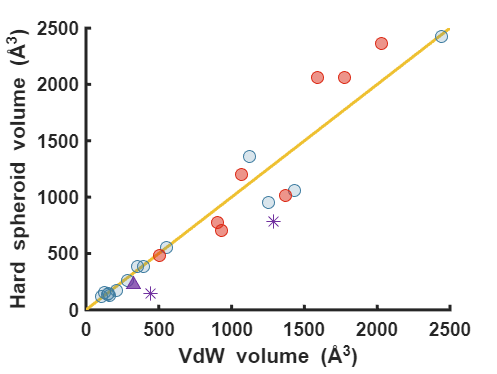



set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('VdW volume (Å^3)','FontName','arial','FontWeight','bold'); 
ylabel('Hard spheroid volume (Å^3)','FontName','arial','FontWeight','bold');
hold off